# Visualizing the Data from Protocol1

%You need to be in the '7-11-2017 Protocol1' folder

%Folder can be "saline_only" or "chicken5x4x1cm" or "screw-2mm-0.8cm" or "screw-3mm-1.2cm" or "screw-3mm-1.5cm"
folder = 'saline_only';

height = '29.6cm';

%Frequency can be...
    %2 (5.832 GHz)
    %3 (7.29 GHz))
    %4 (8.748 GHz)
    %5 (10.206 GHz)
frequency = '4';

%Specify the dacmin and dacmax values (default: dacmin = 949, dacmax = 1100)
dacmin = '1000';
dacmax = '1400';

%Specify whether to plot the baseband or rf data"
mode = 'bb';

%Specify which of the 5 fast time sequences
fts = 1;

%Specify whether the x axis is in bins or meters
x_units='m';

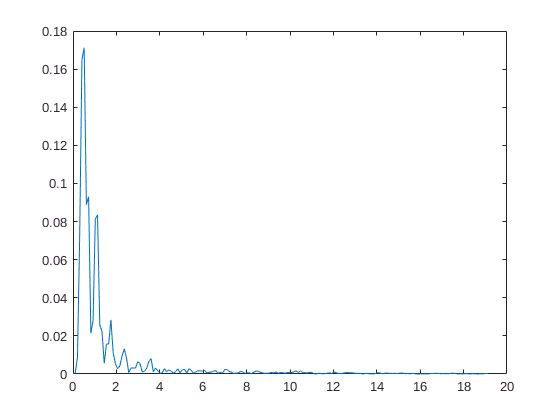


%Create x
if strcmp(mode,'bb')
    x=linspace(1,186,186);
else 
    x=linspace(1,1520,1520);
end

if (strcmp(x_units,'m') && strcmp(mode,'bb'))
    x=x*((299792458)/(2.916*(10^9)));
end

if (strcmp(x_units,'m') && strcmp(mode,'rf'))
    x=x*((299792458)/(23.328*(10^9)));
end

data = obtain_data(folder, height, frequency, dacmin, dacmax, mode, fts);

%Draw the plots (loop through the folder)
if (strcmp(mode,'bb'))
    plot(x,abs(data));
else
    plot(x,data);   
end